t=(0:0.5:120);
k=0.05;
y=75*exp(-k.*t);
linear=log(y);
element=zeros(1,4);
for a=0:2
    sum=0;
    for b=1:241
        temp=(t(1,b)^a);
        sum=sum+temp;
    end
    element(1,a+1)=sum;
end
P=[element(1,1) element(1,2); element(1,2) element(1,3)];

## B

element=zeros(1,2);
for a=1:2
    sum=0;
    for b=1:241
        temp=(linear(1,b))*(t(1,b)^(a-1));
        sum=sum+temp;
    end
    element(1,a)=sum;
end
B=(element)';

## To find A,a,b from PA=B

A=(inv(P))*B;

## Fitting linear line

linear2=A(2,1).*t+A(1,1);

## figure

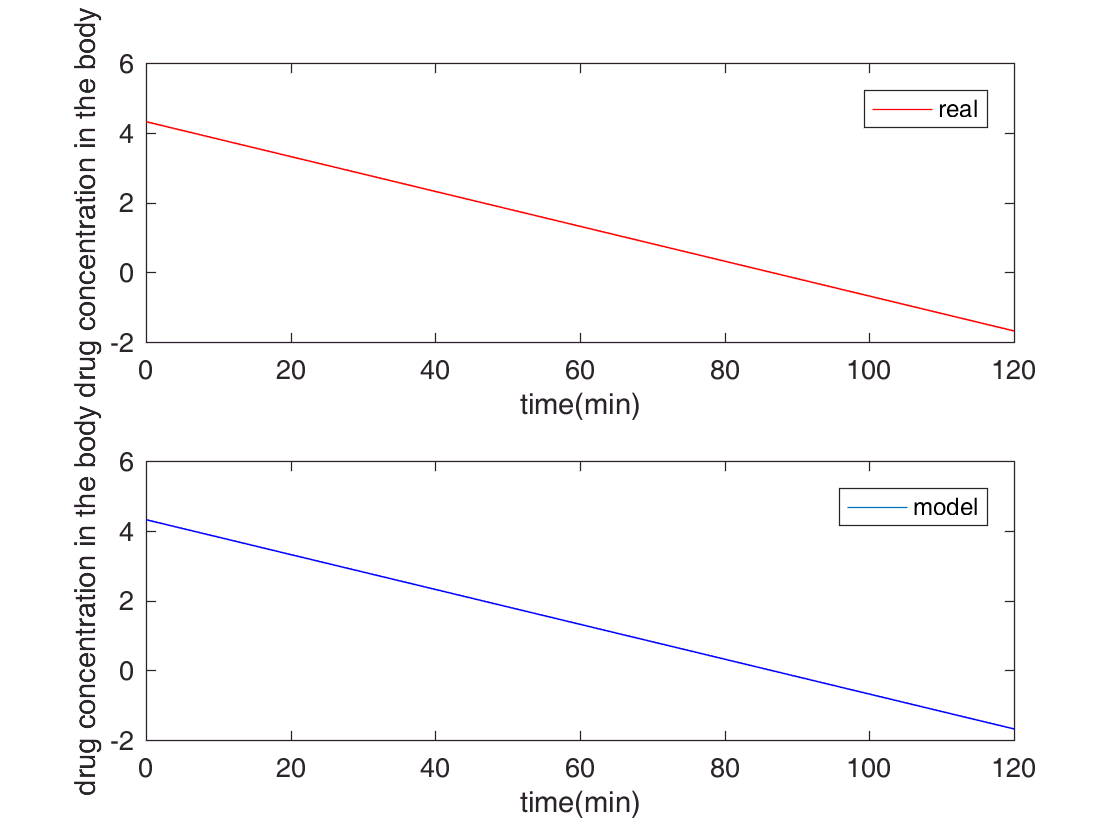

figure(1);
subplot(211);
plot(t,linear2,'r');
xlabel('time(min)');
ylabel('drug concentration in the body');
legend('real');
subplot(212);
plot(t,linear,'b');
xlabel('time(min)');
ylabel('drug concentration in the body');
legend('model');
hold on